# **Procesamiento de Imagenes Digitales**

**Taller 15**

#### Distorsión de Barril

Cargue y visualice (con título) la imagen “trui.png”.

I = imread('trui.png');
figure;imshow(I);title('Original Image','Interpreter','latex');

Obtenga las coordenadas cartesianas de los pixeles de la imagen, tomando como origen de referencia el centro de la imagen y discriminando entre $x$ y $y$. Grafique en un `subplot` horizontal utilizando la función `mesh`.  

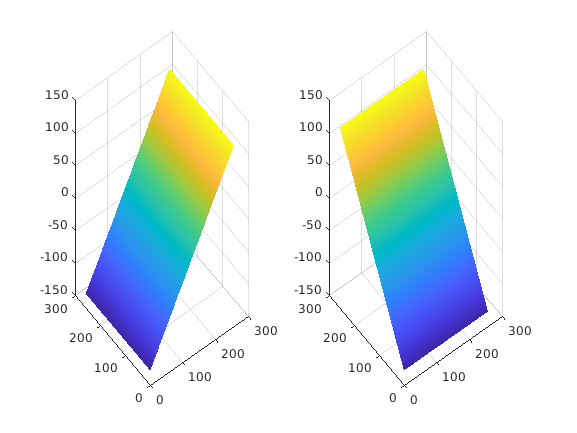

[x,y] = meshgrid(-127:1:128);                                
figure;
subplot(1,2,1);mesh(x);
subplot(1,2,2);mesh(y);

Convierta las coordenadas cartesianas a coordenadas polares utilizando la función: `[tetha,r]=cart2pol(x(:),y(:))`

[theta,r]=cart2pol(x(:),y(:));

Con un coeficiente $a=0.0005$ calcule la distorsión de barril. 

a=0.0005;
s=r+a*r.^3;

Una vez calculada la distorsión de barril, vuelva de coordenadas polares a cartesianas usando la función `[u,v]=pol2car(theta,s). `Reacomode los vectores de coordenadas cartesianas afectados por la distorsión de barril en arreglos 2D. $x'$ y $y'$, con origen en la esquina de la matriz. Grafique en un subplot horizontal utilizando la función mesh.

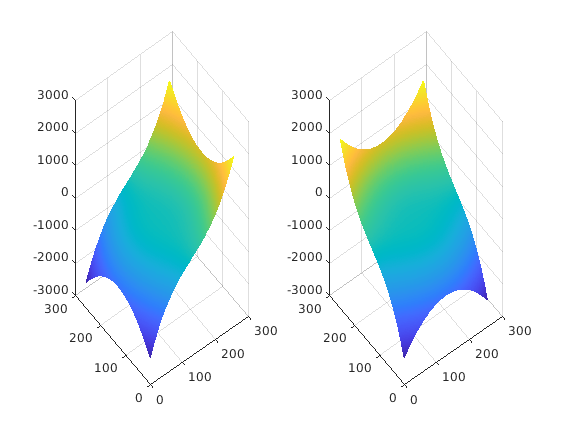

[u,v] = pol2cart(theta,s);
xd = reshape(u, size(I));
yd = reshape(v, size(I));
figure;
subplot(1,2,1);mesh(xd);
subplot(1,2,2);mesh(yd);

Ahora para distorsionar la imagen original requiere de la función:

[`B = tformarray(A,T,R,tdims_A,tdims_B,tsize_B,tmap_B,F)`](https://www.mathworks.com/help/images/ref/tformarray.html#d122e235054)

Para mayor información puede consultar la documentación, sin embargo, en resumen `A` será la imagen original, no requiere ninguna transformación lieal `T`, `R` será la estructura de re muestreo la cual puede construir `‘lienal’` y `‘llenando’` con la función `makeresampler`, las dimensiones de la transformación de entrada `tdims_A` y de salida `tdims_B` serán `[2 1] `y `[1 2]`, respectivamente, por ser imágenes 2D, el tamaño de la matriz de salida `tsize_B` es mejor que se dimensione automáticamente, y el mapeo de coordenadas `tmap_B` que comprende la distorsión de barril debe ser la matriz con la concatenación de los dos arreglos 2D de coordenadas cartesianas $u$ y $v$, finalmente los valores para rellenar F en caso de espacios pueden tener cualquier nivel de gris que usted considere preferiblemente negro. Visualice la imagen distorsionada.

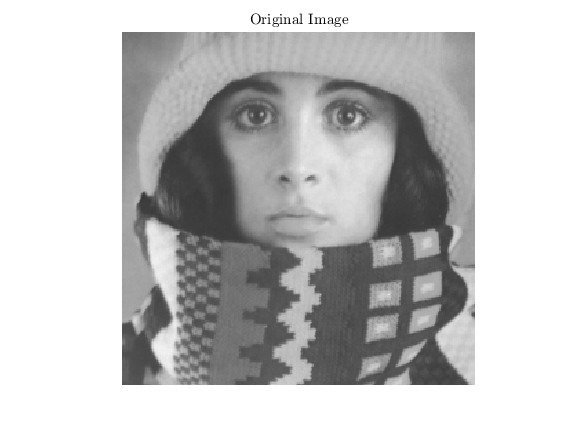

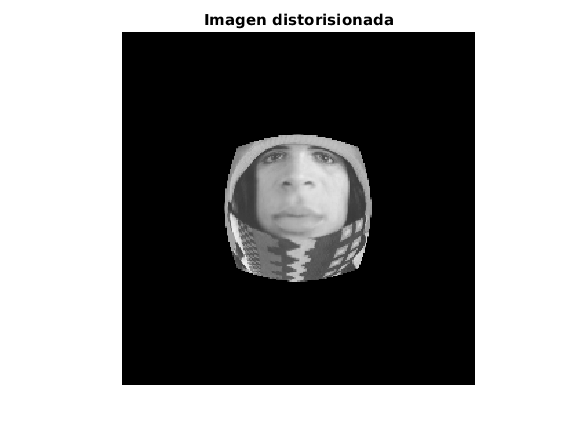

R = makeresampler('linear', 'fill');
J = tformarray(I, [], R, [2 1], [1 2], [], cat(3, xd+128, yd+128), []);
figure(4); imshow(J); title("Imagen distorisionada");

#### Distorsión de Corsé

Repita el procedimiento anterior con un coeficiente $a=0.000015$ y aplique a la imagen original una distorsión de corsé.

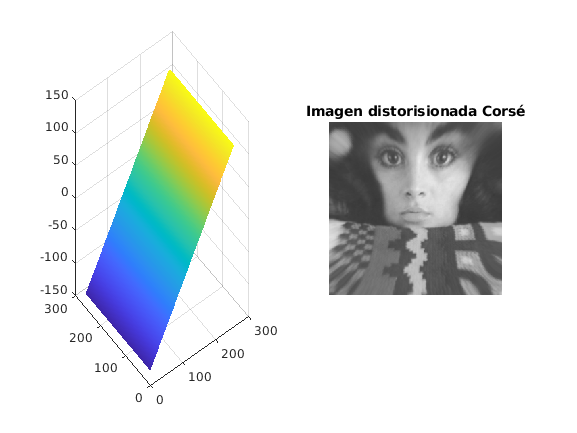

a = -0.000015;
s = r + a .* r.^3;
[u, v] = pol2cart(theta, s);
xp = reshape(u, size(I));
yp = reshape(v, size(I));
R = makeresampler('linear', 'fill');
J = tformarray(I, [], R, [2 1], [1 2], [], cat(3, xp+128, yp+128), []);
figure(5); imshow(J); title("Imagen distorisionada Corsé");